# ELEC4621 Lab 4

***By Jason Ha (z5115925)***

## ***Question 2***

### ***Part (a)***

We can compute the denominator polynomial of this all-pole transfer function to be:


$$D\left(z\right)=\left(z+0\ldotp 51432\right)\left(z+0\ldotp 4417\right)\left(z^2 -2\left(0\ldotp 9562\right)\mathrm{cos}\left(0\ldotp 45\pi \right)+0\ldotp {9562}^2 \right)$$


Might be easier if we compute the coefficients in MATLAB and let it do the expanding for us:

p1 = [1, 0.51432];
p2 = [1, 0.4417];
p3 = [1, -0.9562*exp(1i*0.45*pi)];
p4 = [1, -0.9562*exp(-1i*0.45*pi)]

p4 =    1.0000 + 0.0000i  -0.1496 + 0.9444i



% Expand by convolving each array:
tmp = conv(p3,p4);
tmp2 = conv(p1,p2);
D = conv(tmp, tmp2);
D

D =     1.0000    0.6569    0.8555    0.8061    0.2077


The final transfer function is:


$$H\left(z\right)=\frac{1}{z^4 +1\ldotp 2552z^3 +1\ldotp 4275z^2 +0\ldotp 9421z+0\ldotp 2077}$$


### Part (b)

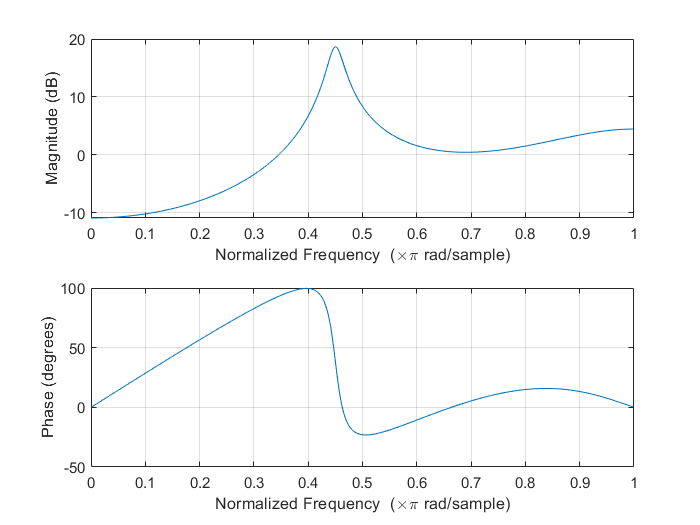

num = 1;
den = D;
freqz(num,den)

### Part (c) (i)

Suppose now we quantise the magnitude and phase and of the poles and zeros such that they are now 4-bit quantised (with respect to their binary representation). We'll dedicate two bits for the integers and 2 bits for the fraction bits. This would give us a 2.2 representation of those values in the form:


$$I_1 I_0 \;\ldotp F_1 F_0$$


We can use the *quantize *and the* numerictype* function to help quantise these values for us. 

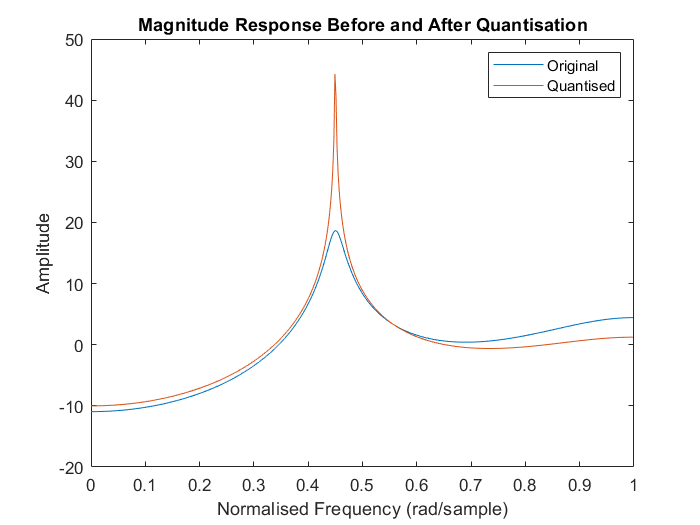

% Quantised numerictype to be a signed 4-bit word length, 2-bit fraction
% length datatype.
ntBP = numerictype(1,4,2);

% Intialise the values first before quantisation. We'll start the magnitude
% values for each pole.
r1 = fi(0.51432);
r2 = fi(0.4417);
r3 = fi(-0.9562);
r4 = fi(-0.9562);

% Initialise the phases for each complex pole
w1 = fi(0.45*pi);
w2 = fi(-0.45*pi);

% Quantise each value:
r1 = quantize(r1, ntBP);
r2 = quantize(r2, ntBP);
r3 = quantize(r3, ntBP);
r4 = quantize(r4, ntBP);
w1 = quantize(w1, ntBP);
w2 = quantize(w2, ntBP);

% Now we initialise the polynomials again but with the quantised values:
p1q = [1, double(r1)];
p2q = [1, double(r2)];
p3q = [1, double(r3)*exp(1i*1.4137)];
p4q = [1, double(r4)*exp(1i*-1.4137)];
den_q = conv(conv(p1q, p2q), conv(p3q, p4q));
num_q = 1;

% Produce the frequency response and plot on top of the original:
[H,W] = freqz(num,den);
[Hq,Wq] = freqz(num_q, den_q);

% Plot the magnitude and phase responses of the original and quantised
% transfer function on the same plot:
figure
plot(W/pi, 20*log10(abs(H)))
hold on
plot(Wq/pi, 20*log10(abs(Hq)))
legend("Original", "Quantised")
title("Magnitude Response Before and After Quantisation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")

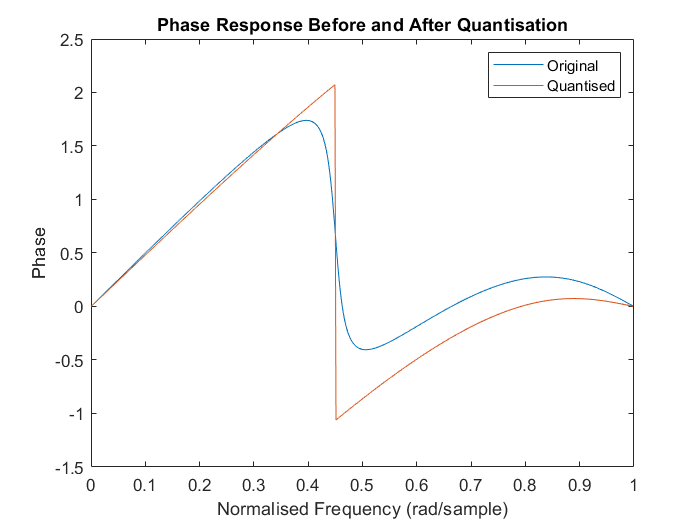


% Plot the same thing for the phase response:
figure
plot(W/pi, angle(H))
hold on
plot(Wq/pi, angle(Hq))
legend("Original", "Quantised")
title("Phase Response Before and After Quantisation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Phase")

### Part (c) (ii)

Now we want to perform the same quantisation but first express all poles in the form:


$$p=z_R +{jz}_I$$


And quantise their real and imaginary parts. Half of the work is done for us for two poles, $p_1$ and $p_2$ that are simply all real poles. We will need to convert the complex valued poles in their existing polar form to rectangular form first.

% Convert complex poles to rectangular form first:
[x3, y3] = pol2cart(0.45*pi, 0.9562);
[x4, y4] = pol2cart(-0.45*pi, 0.9562);

% Quantise a3, a4 and b3, b4 using the same numerictype quantisation:
x3 = double(quantize(fi(x3), ntBP))

x3 = 0

x4 = double(quantize(fi(x4), ntBP))

x4 = 0

y3 = double(quantize(fi(y3), ntBP))

y3 = 0.7500

y4 = double(quantize(fi(y4), ntBP))

y4 = -1

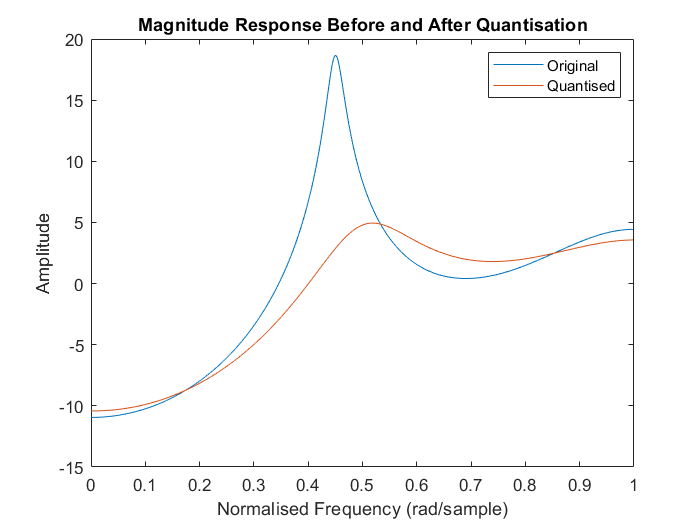


% Recombine the real and imaginary parts of each poles before performing
% polynomial convolution.
pole3 = x3 + j*y3;
pole4 = x4 + j*y4;

p3q2 = [1, -pole3];
p4q2 = [1, -pole4];

den_q2 = conv(conv(p1q, p2q), conv(p3q2, p4q2));
num_q2 = 1;

% Produce the new frequency response:
[Hq2, Wq2] = freqz(num_q2, den_q2);

% Generate the frequency response like in the previous part.
figure
plot(W/pi, 20*log10(abs(H)))
hold on
plot(Wq/pi, 20*log10(abs(Hq2)))
legend("Original", "Quantised")
title("Magnitude Response Before and After Quantisation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")

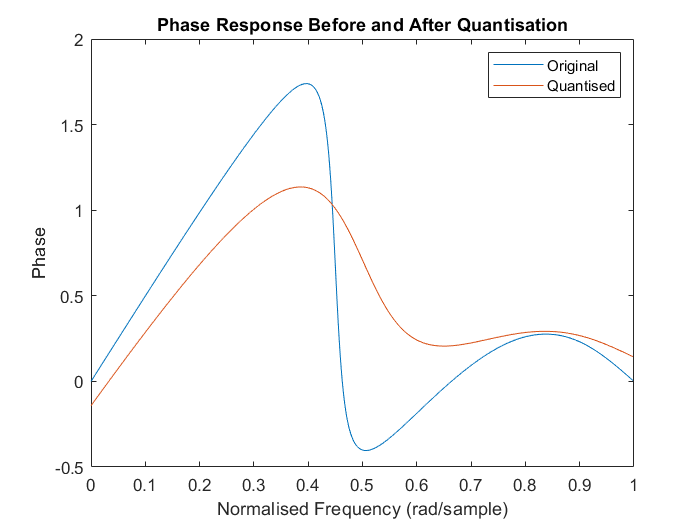


% Plot the same thing for the phase response:
figure
plot(W/pi, angle(H))
hold on
plot(Wq/pi, angle(Hq2))
legend("Original", "Quantised")
title("Phase Response Before and After Quantisation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Phase")

### Part (d)

The cascade implementation consists of two second order sections, $H_1 \left(z\right)$ and $H_2 \left(z\right)$ such that:


$$H_2 \left(z\right)=\frac{1+a_3 z^{-1} +a_4 z^{-2} }{1+b_3 z^{-1} +b_4 z^{-2} }$$



$$H_1 \left(z\right)=\frac{a_0 +a_1 z^{-1} +a_2 z^{-2} }{1+b_1 z^{-1} +b_2 z^{-2} }$$



$$H\left(z\right)=H_2 \left(z\right)\cdot H_{1\;} \left(z\right)$$


Given our poles, our transfer function is in the form:


$$H\left(z\right)=\frac{1}{\left(z-p_1 \right)\left(z-p_2 \right)}\cdot \;\frac{1}{\left(z-p_3 \right)\left(z-p_4 \right)}\equiv H_2 \left(z\right)\cdot H_{1\;} \left(z\right)\;$$


Keeping as many of the digits for each coefficient in the transfer function as possible, substituting the poles, expanding and simplifying gives us the following transfer function:


$$H\left(z\right)=\frac{1}{z^2 +0\ldotp 95602z+0\ldotp 227175144}\cdot \frac{1}{z^2 -\left\lbrack 1\ldotp 9124\mathrm{‬cos}\left(0\ldotp 45\pi \right)\right\rbrack z+0\ldotp 91431844}$$


Comparing coefficients right now, we have the following:


$$a_3 =a_4 =1\;\;\;\;\;\mathrm{and}\;\;\;\;\;a_0 =0$$



$$b_3 =0\ldotp 95602$$



$$b_4 =0\ldotp 227175144$$



$$b_1 =-1\ldotp 9124\mathrm{‬cos}\left(0\ldotp 45\pi \right)$$



$$b_2 =$$

$$0\ldotp 91431844$$


We now want to quantise these coefficients and re-compute the poles and then compare them to the poles from the previous sections.

% Initialise
b1 = -1.9124*cos(0.45*pi);
b2 = 0.91431844;
b3 = 0.95602;
b4 = 0.227175144;

% Quantise:
b1q = double(quantize(fi(b1), ntBP));
b2q = double(quantize(fi(b2), ntBP));
b3q = double(quantize(fi(b3), ntBP));
b4q = double(quantize(fi(b4), ntBP));

% Initialise arrays for each unquantised polynomial
den_C1 = [1 b3 b4];
num_C1 = 1;
den_C2 = [1 b1 b2];
num_C2 = 1;

% Initialise arrays for each polynomial ('C' means 'cascade' e.g. C1 =
% Cascade 1"
den_C1q = [1 b3q b4q];
num_C1q = 1;
den_C2q = [1 b1q b2q];
num_C2q = 1;

% Generate the transfer functions for each:
H_C1q = tf(num_C1q, den_C1q);
H_C2q = tf(num_C1q, den_C2q);

### Part (e) (i)

The resulting transfer function after quantisation is:


$$H_q \left(z\right)=\frac{z^{-2} }{1-0\ldotp 5z^{-1} +0\ldotp 75z^{-2} }\cdot \;\frac{z^{-2} }{1+0\ldotp 75z^{-1} }$$


### Part (e) (ii)

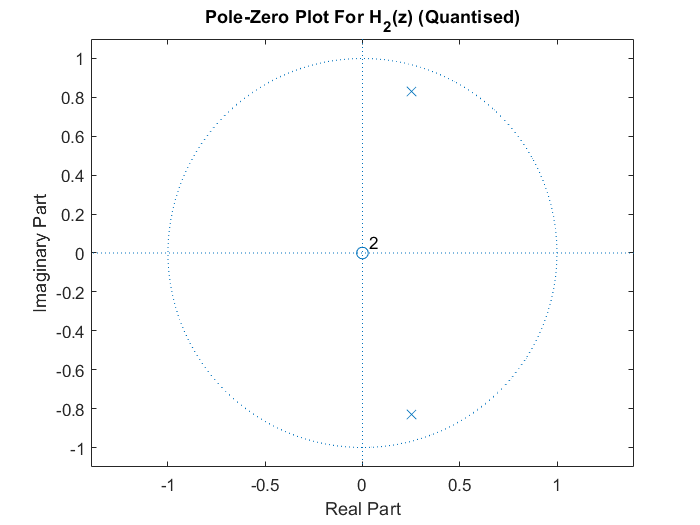

% Generate the pole-zero plot for the above transfer functions as well as
% the transfer function with unquantised coefficients.
figure
zplane(num_C2q, den_C2q);
title("Pole-Zero Plot For H_2(z) (Quantised)")

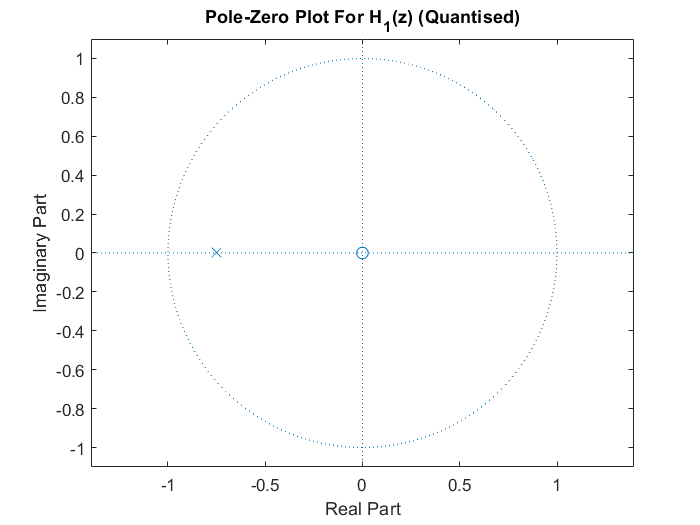


figure
zplane(num_C1q, den_C1q);
title("Pole-Zero Plot For H_1(z) (Quantised)")

The first notable difference from the quantisation is the removal of one of the poles from $H_1 \left(z\right)$. Namely, the quantisation consequently rounded the coefficient $b_4$ to 0. Since $b_4$ is a coeffcient of $z^{-2}$, the denominator polynomial of $H_1 \left(z\right)$ has reduced to an order 1 polynomial as a result of the quantisation. The quantisation of the coefficients in $H_2 \left(z\right)$ fortunately has allowed it to retain its two poles.

Of course, the positions of the poles must be drastically different compared to the pole-zero plots of these quantised versions.

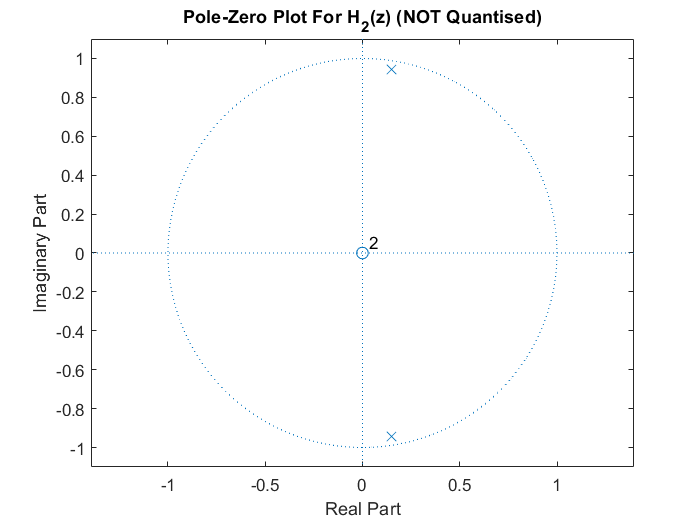

figure
zplane(num_C2, den_C2)
title("Pole-Zero Plot For H_2(z) (NOT Quantised)")

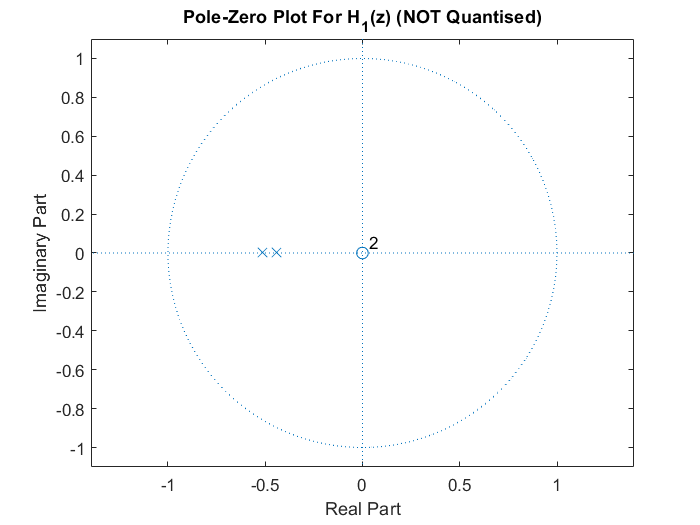


figure
zplane(num_C1, den_C1)
title("Pole-Zero Plot For H_1(z) (NOT Quantised)")

### Part (e) (iii)

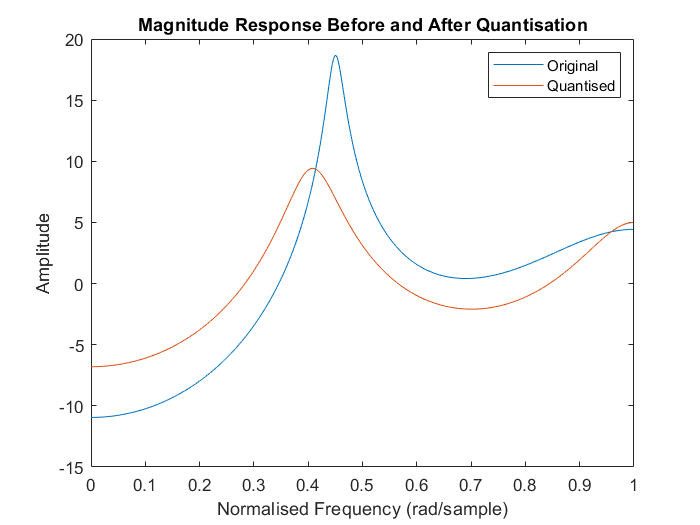

[HN, WN] = freqz(conv(num_C2,num_C1), conv(den_C2,den_C1));
[HqC, WqC] = freqz(conv(num_C2q,num_C1q), conv(den_C2q,den_C1q));

% Plot the magnitude and phase responses of the original and quantised
% transfer function on the same plot:
figure
plot(WN/pi, 20*log10(abs(HN)))
hold on
plot(WN/pi, 20*log10(abs(HqC)))
legend("Original", "Quantised")
title("Magnitude Response Before and After Quantisation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Amplitude")

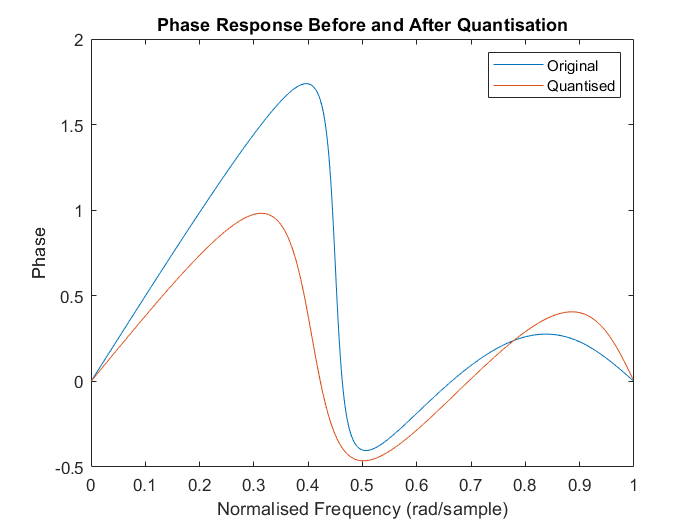


% Plot the same thing for the phase response:
figure
plot(WN/pi, angle(HN))
hold on
plot(WN/pi, angle(HqC))
legend("Original", "Quantised")
title("Phase Response Before and After Quantisation")
xlabel("Normalised Frequency (rad/sample)")
ylabel("Phase")